# Three-body problem (/^▽^)/

For once, I'll have to use Sauer's code since I don't quite have time to write my own...

NB: The plots would have been much prettier if we could use the trapezoid method (I *have* tested) – but alas, the original orbit.m code only uses Euler's method.

Testing the one-body problem:

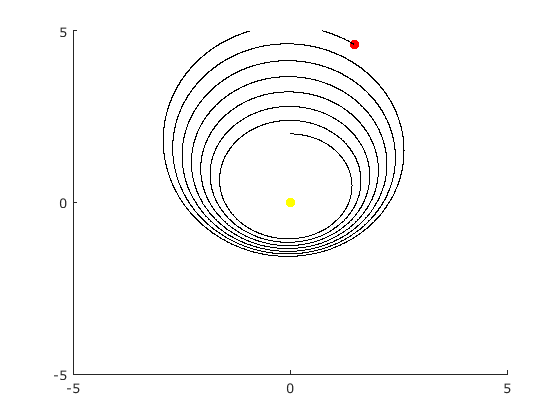

orbit([0 100],[0 1 2 0],10000,100,5,1, ...
    @eulerstep, ...
    @(m,x) ydot(m,x)) % fml

## CP10

Adapt orbit.m to solve the three-body problem.

Set the masses to m1 = 0.3, m2 = m3 = 0.03.

**NO:** Apparently the problem in the book is incorrect, or just does not correspond to the solution that the student assistants have got. It also looks rather weird and doesn't change much in the second subproblem – but the problem text indicates that it is supposed to change by *a lot*.

With all masses set to 0.3, it looks fine and behaves as expected

**(a)** Plot the trajectories with initial conditions

(x1,y1) = (2,2), (x′1,y′1) = (0.2,−0.2),

(x2,y2) = (0,0), (x′2,y′2) = (0,0) and

(x3,y3) = (−2,−2),(x′3,y′3) = (−0.2,0.2).

We have *four* sets of ODEs for each body, a total of *twelve* ODEs to solve.

m = [0.3 0.3 0.3];
p =1000;
g = 1;
T = 10000;
N = 100000;
init = [2 0.2 2 -0.2 0 0 0 0 -2 -0.2 -2 0.2];

orbit([0 T],init,N,p,30,3, ...
    @eulerstep, ...
    @(~,x) threebody(m,g,x)) % fml

**(b)** Change the initial condition of x′1 to 0.20001, and compare the resulting trajectories.

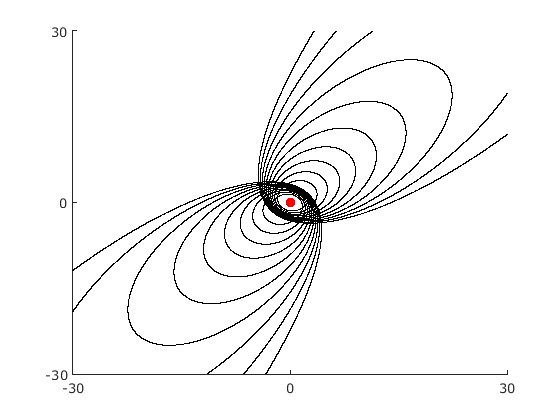

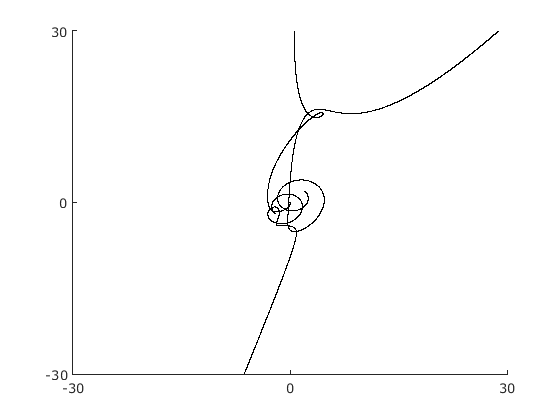

init(2) = 0.20001;
orbit([0 T],init,N,p,30,3, ...
    @(t,y,h,f) eulerstep(t,y,h,f), ...
    @(~,x) threebody(m,g,x))

## CP11

Uniform masses and gravitation

Set the masses to m1 = m2 = m3 = 1 and gravity g = 1.

**(a)** Adapt orbit.m to plot thetrajectory with initial conditions

(x1,y1) = (−0.970,0.243), (x′1,y′1) = (−0.466,−0.433),

(x2,y2) = (−x1,−y1), (x′2,y′2) = (x′1,y′1),

and (x3,y3) = (0,0), (x′3,y′3) = (−2x′1,−2y′1).

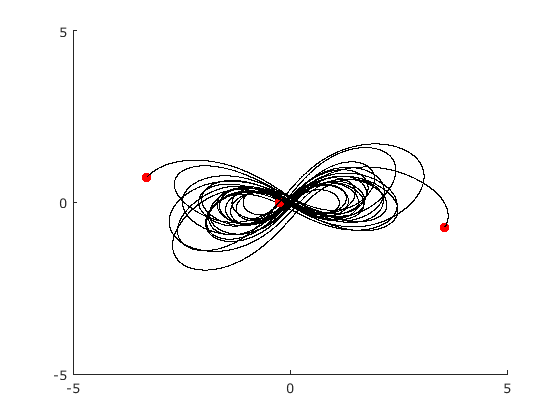

m = [1 1 1];
g = 1;
p = 50;
T = 100;
N = 10000;
init = [-0.97 -0.466 0.243 -0.433 0.97 -0.466 -0.243 -0.433 0 2*0.466 0 2*0.433];
orbit([0 T],init,N,p,5,3, ...
    @(t,y,h,f) eulerstep(t,y,h,f), ...
    @(~,x) threebody(m,g,x))

**(b) **Are the trajectories sensitive to small changes in initial conditions? Investigate the effect of changing x′3 by $10^{-k}$ for 1 ≤ k ≤ 5. For each k, decide whether the figure-eight pattern persists.

%for k=1:5
%    init(10) = init(10) * 0.1;
%    orbit([0 T],init,N,p,20,3, ...
%        @(t,y,h,f) eulerstep(t,y,h,f), ...
%        @(~,x) threebody(m,g,x))
%end

Using a foor loop ended up giving *one* plot. Because of that, I simply unwrap it:

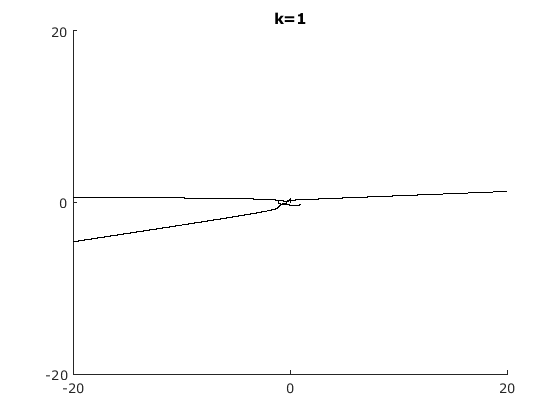

% k = 1
init(10) = init(10) * 0.1;
orbit([0 T],init,N,p,20,3, ...
    @(t,y,h,f) eulerstep(t,y,h,f), ...
    @(~,x) threebody(m,g,x))
title('k=1')
% k = 2
init(10) = init(10) * 0.1;
orbit([0 T],init,N,p,20,3, ...
    @(t,y,h,f) eulerstep(t,y,h,f), ...
    @(~,x) threebody(m,g,x))

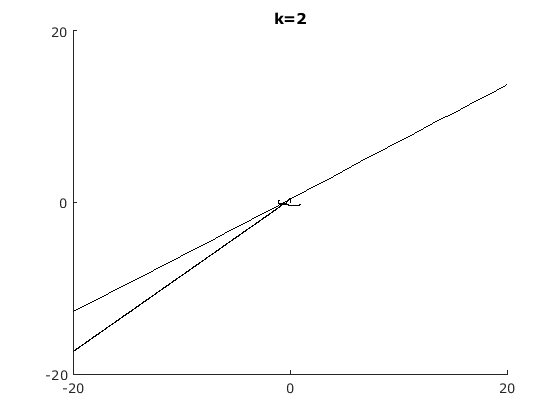

title('k=2')
% k = 3
init(10) = init(10) * 0.1;
orbit([0 T],init,N,p,20,3, ...
    @(t,y,h,f) eulerstep(t,y,h,f), ...
    @(~,x) threebody(m,g,x))

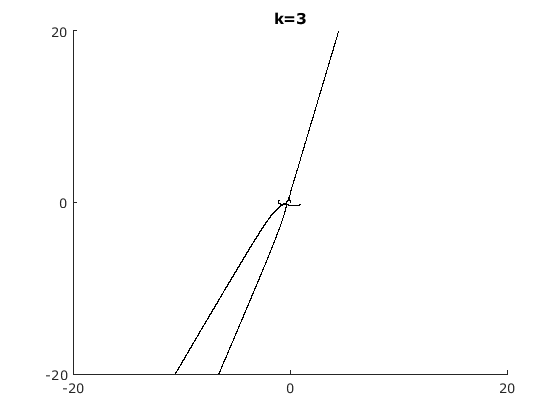

title('k=3')
% k = 4
init(10) = init(10) * 0.1;
orbit([0 T],init,N,p,20,3, ...
    @(t,y,h,f) eulerstep(t,y,h,f), ...
    @(~,x) threebody(m,g,x))

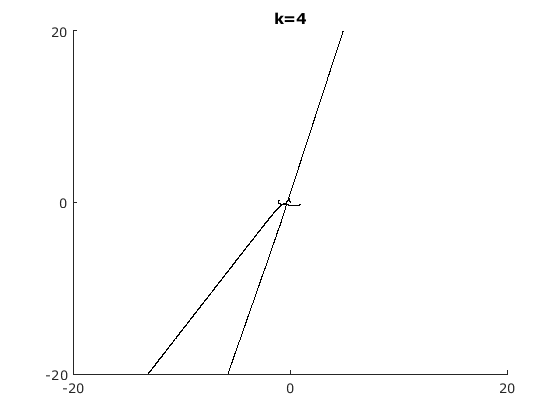

title('k=4')
% k = 5
init(10) = init(10) * 0.1;
orbit([0 T],init,N,p,20,3, ...
    @(t,y,h,f) eulerstep(t,y,h,f), ...
    @(~,x) threebody(m,g,x))

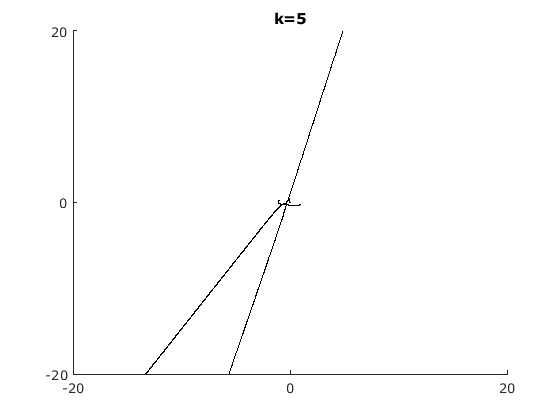

title('k=5')

Conclusion: Even at k=1, the orbits look very different. A tiny deviation is enough to toppe it.

function orbit(inter,ic,n,p, scale, numBodies, step, slope)
%ORBIT Plotting FUNCTION for ANY m-body problem
%       inter: interval in time
%       initial conditions ic:
%       [xi vxi yi vyi ...]
%       n: number of steps
%       p: steps per point plotted
%       step: RK step function (e.g. Euler)
%       slope: equation iterator

h=(inter(2)-inter(1))/n; % plot n points
y(1,:)=ic;
t = linspace(inter(1), inter(2), n+1);
t(1)=inter(1); % build y vector


% Set various f-ing deprecated options ---
% now they are replaced
set(gca,'XLim',[-scale scale],'YLim',[-scale scale], ...
        'XTick',[-scale 0 scale],'YTick',[-scale 0 scale], ...
        'SortMethod','childorder','Visible','on');
cla;

% (there should be no sun for 3-body problem)
if numBodies == 1
    line('color','y','Marker','.','markersize',25,...
             'xdata',0,'ydata',0);
    drawnow;
end

% Set up body points
for i=1:numBodies
    heads(i)=line('color','r','Marker','.','markersize',25,...
          'xdata',[],'ydata',[]);
    tails(i)=line('color','b','LineStyle','-', ...
          'xdata',[],'ydata',[]);
    lines(i) = animatedline();
end

%[px,py]=ginput(1);% include these three lines
%[px1,py1]=ginput(1);% to enable mouse support
%y(1,:)=[px px1-px py py1-py];% 2 clicks set direction


for k=1:n/p
    for i=1:p
        y(i+1,:)=step(t(i),y(i,:),h, slope);
    end
    % overwrite previous results
    y(1,:)=y(p+1,:);
    t(1)=t(p+1);
    
    % add data to each individual body
    % spaced at (i-1)*4 into the array
    for i=1:numBodies
        a = (i - 1)*4;
        set(heads(i),'xdata',y(1,1+a),'ydata',y(1,3+a))
        set(tails(i),'xdata',y(2:p,1+a),'ydata',y(2:p,3+a))
        addpoints(lines(i), y(2:p,1+a), y(2:p,3+a));
    end
    drawnow update;
end

end

function y=eulerstep(t,x,h, slope)
    %one step of the Euler Method
    y=x+h*slope(t,x);
end

% Standard trapezoid step
function y=trapezoid(t, x, h, slope)
    s1 = slope(t, x);
    s2 = slope(t+h, x + h*s1);
    y = x + h*(s1+s2)/2;
end


function z=threebody(m,g,x)
% x contains [px1 vx1 py1 vy1 px2 vx2 ...]
% extracting them in a more manageable way:
px = [x(1) x(5) x(9)];
py = [x(3) x(7) x(11)];
vx = [x(2) x(6) x(10)];
vy = [x(4) x(8) x(12)];

z = zeros(1,12);

% There are three unique "distances"
dist12 = ((px(2)-px(1))^2 + (py(2)-py(1))^2)^(3/2);
dist13 = ((px(3)-px(1))^2 + (py(3)-py(1))^2)^(3/2);
dist23 = ((px(3)-px(2))^2 + (py(3)-py(2))^2)^(3/2);

% Then six different expressions that use them,
% and six simple insertions.

% Body ONE
z(1) = vx(1);
z(2) = g*m(2)*(px(2)-px(1))/dist12 + g*m(3)*(px(3)-px(1))/dist13;
z(3) = vy(1);
z(4) = g*m(2)*(py(2)-py(1))/dist12 + g*m(3)*(py(3)-py(1))/dist13;

% Body TWO
z(5) = vx(2);
z(6) = g*m(1)*(px(1)-px(2))/dist12 + g*m(3)*(px(3)-px(2))/dist23;
z(7) = vy(2);
z(8) = g*m(1)*(py(1)-py(2))/dist12 + g*m(3)*(py(3)-py(2))/dist23;

% Body THREE
z(9) = vx(3);
z(10) = g*m(1)*(px(1)-px(3))/dist13 + g*m(2)*(px(2)-px(3))/dist23;
z(11) = vy(3);
z(12) = g*m(1)*(py(1)-py(3))/dist13 + g*m(2)*(py(2)-py(3))/dist23;
end

% fkin one-body problem
function z=ydot(~,x)
m2=3;g=1;mg2=m2*g;px2=0;py2=0;
px1=x(1);py1=x(3);vx1=x(2);vy1=x(4);
dist=sqrt((px2-px1)^2+(py2-py1)^2);
z=zeros(1,4);
z(1)=vx1;
z(2)=(mg2*(px2-px1))/(dist^3);
z(3)=vy1;
z(4)=(mg2*(py2-py1))/(dist^3);
end